SIMULATION study showing where harmonic flow excles in capturing recurrent cyclic interactions in a netework with 1-cycle while Granger casuality and structural equation struggle. 

(C) 2026 Moo K. Chung, 

University of Wisconsin-Madison

### Ground Truth 

Building Directed Cyclic Graph (DCG): a directed graph that contains one or more cycles. We build cycle-only ground truth with 4-nodes indexed as 1, 2, 3 and 4. We then add two additional nodes 5 and 6 and connect node 5 to node 2, and node 6 to node 4 

clear; clc; 
Nodes = [cos((0:3)'*2*pi/4) sin((0:3)'*2*pi/4)];  
Edges = [1 2; 2 3; 3 4; 4 1];
X     = [2; 3; 3; 2];   % edge flow strength, edges are indexed following 'Edges'.

Nodes = [Nodes;  
         0   1.8;  % node 5 above node 2
         0  0.2];  % node 6 below node 4

% 
Edges = [Edges;
         2 5;      % edge from 2 -> 5
         6 4];     % edge from 6 -> 4



We then assign an edge flow X along the edge directions and vary the strength of the circulation by attenuating the magnitudes of the remaining edge flows. Subsequently, we simulate random edge flows using a vector autoregressive model with X as the ground truth, and obtain noisy observed node time series Z.

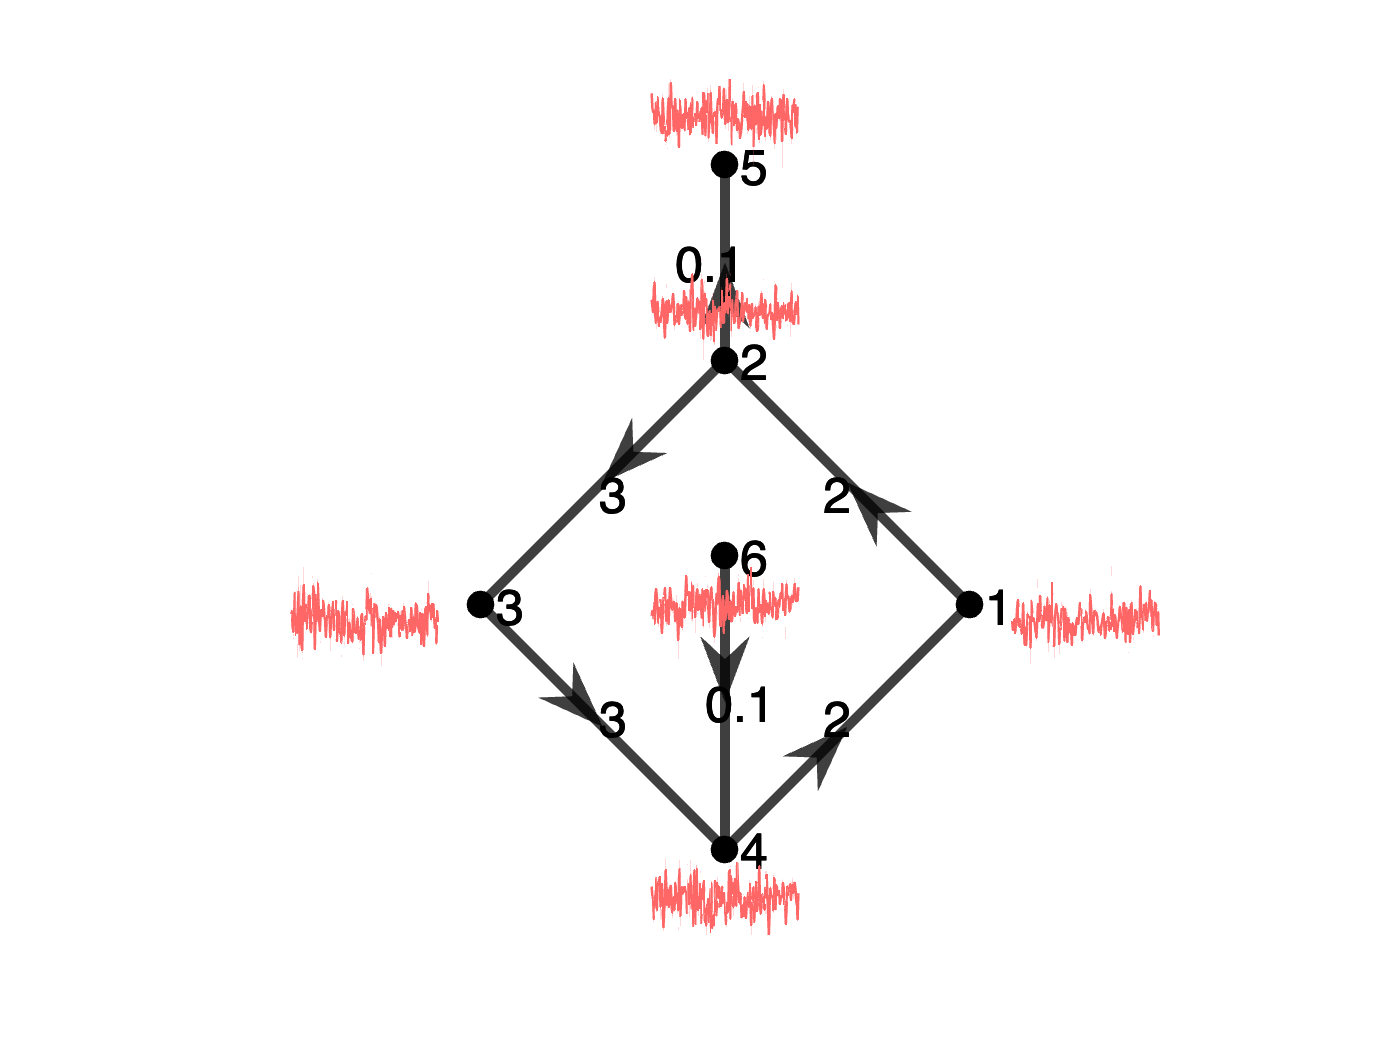

%X = [X; 0; 0];   % Only circulation
X = [X; 0.1; 0.1];   % strong circulation
%X = [X; 5; 5];      % weak circualtion
%X = [X; 100; 100];  %super weak circualtion
figure;  graph_directed_plot(Nodes, Edges, X);
Z= VAR_graph(Edges, X, 4,1);
graph_directed_plot(Nodes, Edges, X);
graph_overlay_timeseries(Nodes, Z)

In the simulation, the ground truth is a cyclic structure encoded in the connectivity matrix, and the goal is to assess whether the proposed method can accurately recover the underlying cyclic flow.

X_truth = [2; 3; 3; 2; 0; 0]'; %ground truth edge flow
C_truth = graph_edge2matrix(Edges, X_truth)

C_truth =      0     2     0    -2     0     0
    -2     0     3     0     0     0
     0    -3     0     3     0     0
     2     0    -3     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


To perform random simulations, we first generate random time series a priori and save them, so that exactly the same realizations are used across all methods. This avoids feeding different time series to different methods and ensures a fair comparison.

noise_levels = [0.1, 1, 10];
Na = numel(noise_levels);
nTrials = 100; %10 trials for faster performance. change it to 100 for publication. 

for a = 1:Na
    sigma = noise_levels(a);  
    for t = 1:nTrials
        Z = VAR_graph(Edges, X, 4, sigma);     % generate one random realization
        Zall(:,:,a,t) = Z;         % store [T x K x Na x nTrials]
    end
end

%save simulationZ.mat  Zall 


### Granger Causality

The implementation follows linear Granger causality within a vector autoregressive (VAR) framework, where the model order is selected using information criteria and directional dependence is quantified via residual-based variance comparisons following Geweke (1982):

Geweke, J. Measurement of linear dependence and feedback between multiple time series. *Journal of the American statistical association* 77 (1982): 304-313.

noise_levels = [0.1, 1, 10];
Na = numel(noise_levels);
nTrials = 10; %10 trials for faster performance. change it to 100 for publication. 

load simulationZ.mat

% Cosine similarity for Granger causality
cos_gc = zeros(Na, nTrials);


for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                 % stored as [K x T]
        % VAR_fit expects X as [N x T] = [nodes x time]
        [A_est, X_pred, GC_matrix, P] = VAR_fit(Z);   
        % Convert p-values to connectivity strength, Smaller p-value = stronger evidence of Granger causality
        What = 1 - GC_matrix;                          % simple monotone conversion
        scG = VAR_score(What, C_truth);
        cos_gc(a,t) = scG.cosine;
    end
end

mGC = mean(cos_gc, 2, 'omitnan');
sGC = std(cos_gc, 0, 2, 'omitnan');

disp(table(noise_levels(:), mGC, sGC, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.33846      0.099838 
       1      0.26975       0.10163 
      10      0.34053       0.10097 



### Structural Equation Model (SEM)

load simulationZ.mat

%Cosine similarity added
cos_nonlinSEM = zeros(Na, nTrials);
%Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z=Zall(:,:,a,t);          % [T x K] from simulator
        out = SEM_nonlinear(Z.');             % out.W_inst is [K x K], i -> j
        scT = VAR_score(out.W_inst, C_truth);
        cos_nonlinSEM(a,t) = scT.cosine;         % <— FIX: store into correct variable
    end
end

mSEMnl = mean(cos_nonlinSEM, 2, 'omitnan');
sSEMnl = std(cos_nonlinSEM, 0, 2, 'omitnan');

disp(table(noise_levels(:), mSEMnl, sSEMnl, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.39515      0.035991 
       1      0.36737      0.037729 
      10      0.38744      0.040654 



### Cyclic Causal Model

cos_ccd = zeros(Na, nTrials);

% Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                    % stored as [K x T]
        out = CCD(Z.', Edges);                % transpose to [T x K] 
        What = out.connectivity;              % [K x K]
        What(1:size(What,1)+1:end) = 0;       % remove self-loops
        
        scT = VAR_score(What, C_truth);
        cos_ccd(a,t) = scT.cosine;
    end
end

mCCD = mean(cos_ccd, 2, 'omitnan');
sCCD = std(cos_ccd, 0, 2, 'omitnan');

disp(table(noise_levels(:), mCCD, sCCD, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))  

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.29417       0.41603 
       1            0             0 
      10      0.58835             0 

